# Adsorption Isotherms for the Pb-Activated Carbon System

## Isotherms for Lead (Pb) Adsorption on Activated Carbon

### Introduction

The equilibrium adsorption is denoted as $q_e$ (mg/g) and has the meaning adsorbate mass over adsorbent mass. 


$$q_e =\frac{\mathrm{adsorbate}\;\mathrm{mass}}{\mathrm{adsorbent}\;\mathrm{mass}}$$


The adsorbate concentration at equilibrium, $C_e$ (mg/L), is the concentration of the adsorbate when the system has reached equilibrium.

### Experiment Data

The data were obtained from an experiment that has the goal of obtaining the isotherm between lead (Pb) and activated carbon.

% The equilibrium adsorption in mg/g.
qe = [20,44,50,90,98]

qe =     20    44    50    90    98


% The equilibrium concentration in mg/L.
Ce = [90,78,75,55,51]

Ce =     90    78    75    55    51


### Plot Adsorption Versus Concentration at Equilibrium

Plotting the experimental produces the following curve.

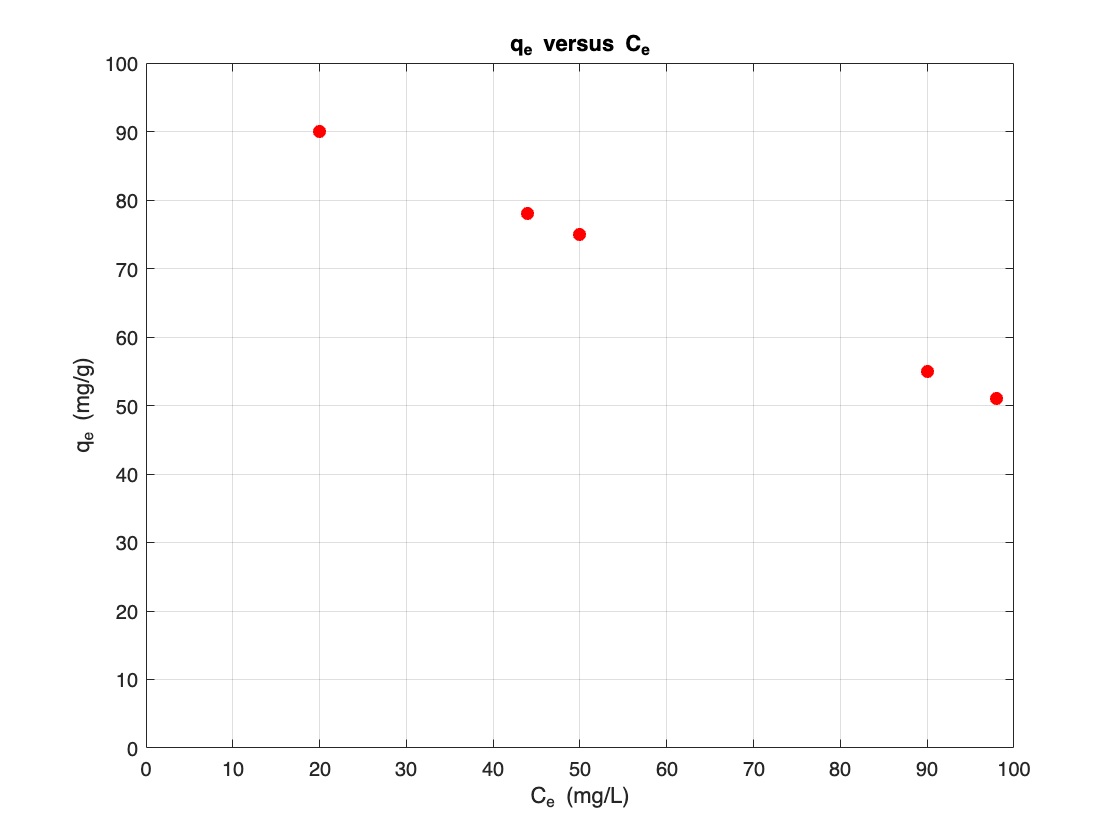

% The maximums and minimums of the axes.
xmax = 100;
ymax = 100;
xmin = 0;
ymin = 0;
% Plot the data.
plot(qe,Ce,'or','MarkerFaceColor','r')
xlim([xmin xmax])
ylim([ymin ymax])
grid on
title("q_e versus C_e")
xlabel("C_e (mg/L)")
ylabel("q_e (mg/g)")

### Calculate the Inverse for Langmuir and Logarithm for Freundlich

Following the Langmuir and Freundlich isotherm equations, $q_e$ needs to be divided by one and multiplied with $C_e$ or the logarithms of $q_e$ and $C_e$ need to be calculated.

#### Langmuir Variables Calculation

% For Langmuir
inv_qe = Ce ./ qe

inv_qe =     4.5000    1.7727    1.5000    0.6111    0.5204


#### Freundlich Variables Calculation

% For Freundlich
logCe = log10(Ce)

logCe =     1.9542    1.8921    1.8751    1.7404    1.7076


logqe = log10(qe)

logqe =     1.3010    1.6435    1.6990    1.9542    1.9912


### Langmuir Isotherm

#### Plot the Langmuir Isotherm Ce/qe Versus Ce

Plotting the isotherm of the system shows an increasing trend.

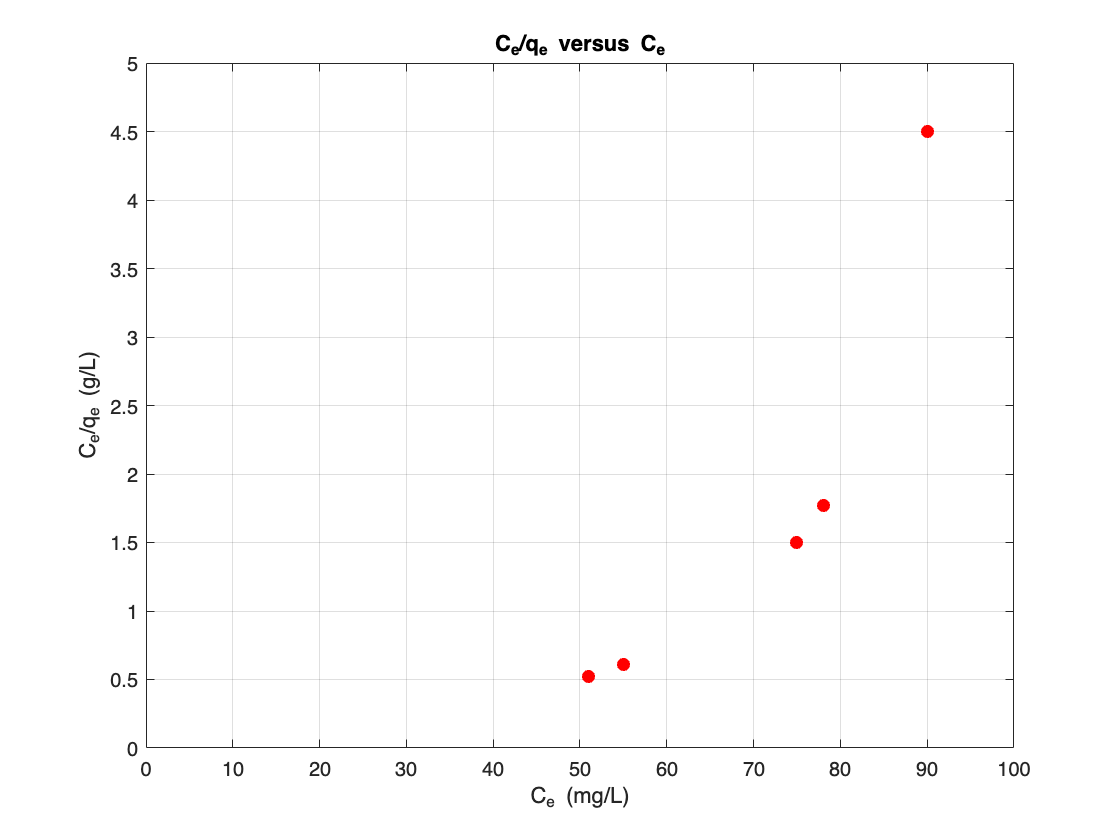

% The maximums and minimums of the axes.
xmax1 = 100;
ymax1 = 5;
xmin1 = 0;
ymin1 = 0;
% Plot Ce/qe versus qe
myplot1(Ce, inv_qe, xmax1, ymax1, xmin1, ymin1)
title("C_e/q_e versus C_e")
xlabel("C_e (mg/L)")
ylabel("C_e/q_e (g/L)")
grid on
hold on

#### Linear Fit through the Langmuir Isotherm

Fitting a linear line through the data allows the estimation of the isotherm adsorption coefficients.

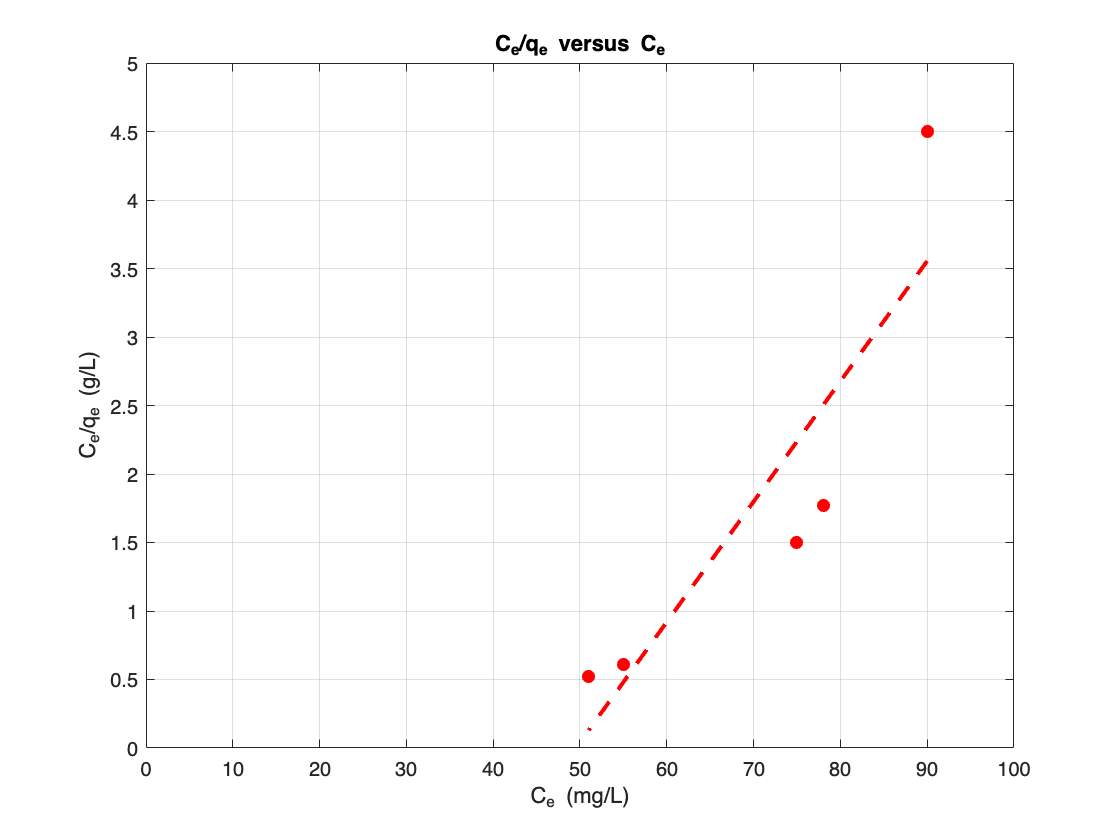

% Fit line to data using polyfit. 
% The value 1 denotes a linear fit.
c = polyfit(Ce,inv_qe,1);
% Evaluate fit equation using polyval
y_est = polyval(c,Ce);
% Add trend line to plot
plot(Ce,y_est,'r--','LineWidth',2)
grid on
hold off

#### The Linear Fit Equation for the Langmuir Isotherm

The linear regression equation is given as follows.

% Display evaluated equation y = m*x + b
disp(['Equation is C_e/q_e = ' num2str(c(1)) '*C_e + ' ...

Equation is C_e/q_e = 0.087838*C_e + -4.3502


    '' num2str(c(2))])

#### The Coefficient of Determination for the Langmuir Isotherm

The coefficient or $R^2$ will indicate the goodness of fit of the linear line to the data. A good fit will have the coefficient near to the value of one.

% Calcuate the correlation coefficient
r_value = corrcoef(Ce,inv_qe);
% The R2 is the square of the correlation coefficient
R2_Langmuir = r_value(1,2)^2

R2_Langmuir = 0.7951

### The Freundlich Isotherm

#### Plot the Freundlich Isotherm lg(qe) Versus lg(Ce)

Plotting the isotherm of the system shows a decreasing trend.

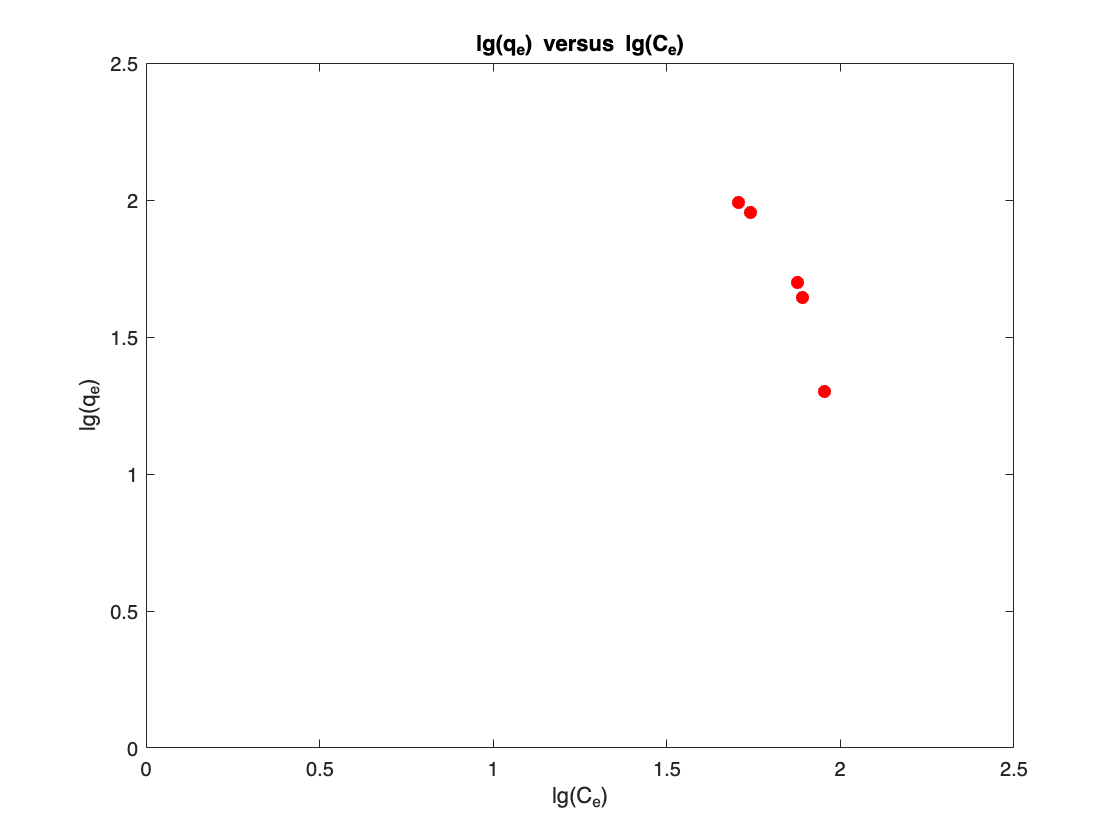

% The maximums and minimums of the axes.
xmax1 = 2.5;
ymax1 = 2.5;
xmin1 = 0;
ymin1 = 0;
% Plot Ce/qe versus qe
myplot1(logCe, logqe, xmax1, ymax1, xmin1, ymin1)
title("lg(q_e) versus lg(C_e)")
xlabel("lg(C_e)")
ylabel("lg(q_e)")
hold on

#### Linear Fit through the Freundlich Isotherm

Fitting a linear line through the data allows the estimation of the isotherm adsorption coefficients.

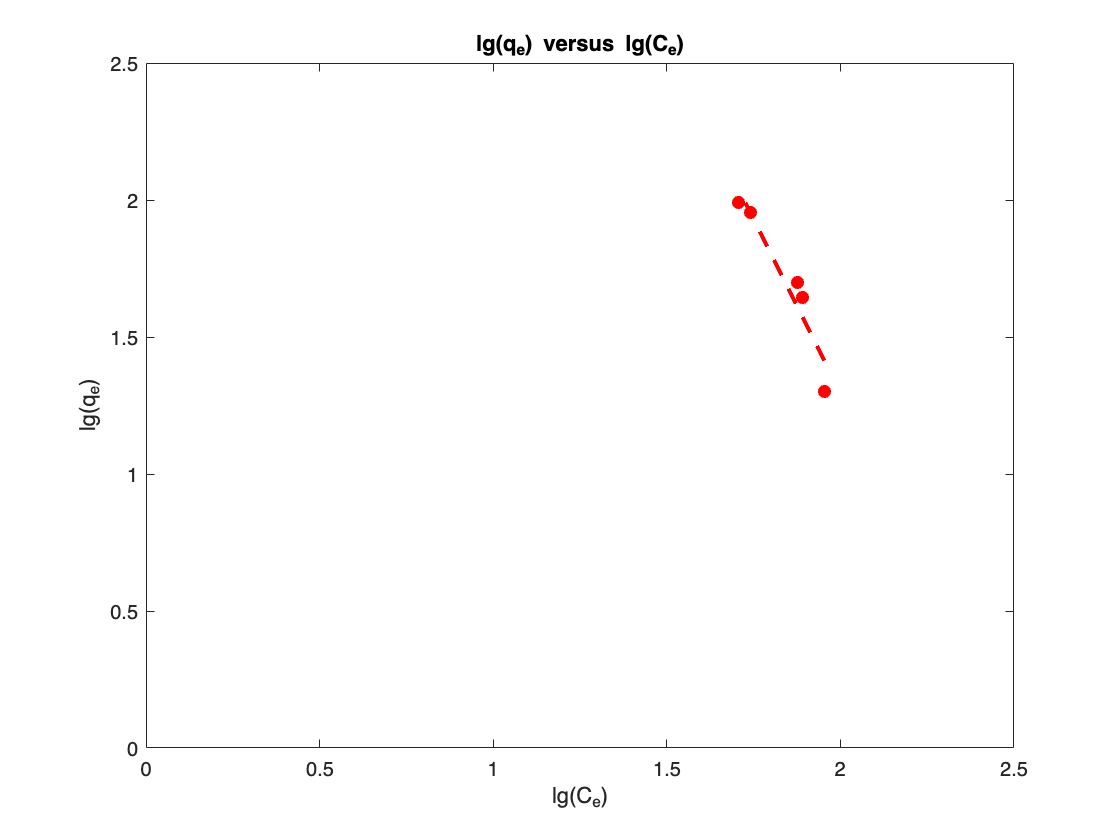

% Fit line to data using polyfit. The value 1 denotes a linear fit.
c = polyfit(logCe,logqe,1);
% Evaluate fit equation using polyval
y_est = polyval(c,logCe);
% Add trend line to plot
plot(logCe,y_est,'r--','LineWidth',2)
hold off

#### The Linear Fit Equation for the Freundlich Isotherm

The linear regression equation is given as follows.

% Display evaluated equation y = m*x + b
disp(['Equation is C_e/q_e = ' num2str(c(1)) '*C_e + ' num2str(c(2))])

Equation is C_e/q_e = -2.5279*C_e + 6.3536


#### The Coefficient of Determination for the Freundlich  Isotherm

The coefficient or $R^2$ will indicate the goodness of fit of the linear line to the data. A good fit will have the coefficient near to the value of one.

% Calcuate the correlation coefficient
r_value = corrcoef(logCe,logqe);
% The R2 is the square of the correlation coefficient
Rsq_Freundlich = r_value(1,2)^2

Rsq_Freundlich = 0.9119

### Local Function

The function used in the live script.

function myplot1(qe, Ce, xmax, ymax, xmin, ymin)
plot(qe,Ce,'or','MarkerFaceColor','r')
xlim([xmin xmax])
ylim([ymin ymax])
end